addpath(genpath('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\MATLABrelated\'))

# Q1:

a)

R_10 = [0, 1; -1, 0];
p10_1 = [-0.5; 4];
p01_1 = -p10_1;
R_01 = R_10'

R_01 =      0    -1
     1     0


p01_0 = R_01 * p01_1

p01_0 =     4.0000
    0.5000


b)

p21_0 = [3;0];
p02_0 = p01_0 - p21_0

p02_0 =     1.0000
    0.5000


c)

p03_0 = [2.5;2.5]

p03_0 =     2.5000
    2.5000


R_03 = rot2(pi/4)

R_03 =     0.7071   -0.7071
    0.7071    0.7071


d)

p04_0 = p02_0 + [0;3.5]

p04_0 =      1
     4


R_04 = rot2(-pi/2)

R_04 =     0.0000    1.0000
   -1.0000    0.0000


ax = gca;

Create Walls

Nwall = collisionBox(5,0.1,1);
Swall = collisionBox(5,0.1,1);
Ewall = collisionBox(0.1,5,1);
Wwall = collisionBox(0.1,5,1);

Wall Poses

Nwall.Pose(:,4) = [5/2;5+0.1/2;0;1];
Swall.Pose(:,4) = [5/2;-0.1/2;0;1];
Ewall.Pose(:,4) = [-0.1/2;5/2;0;1];
Wwall.Pose(:,4) = [5+0.1/2;5/2;0;1];

Wall show

hold off
show(Nwall,'Parent',ax)
hold on
show(Swall,'Parent',ax)
show(Ewall,'Parent',ax)
show(Wwall,'Parent',ax)
view(0,90)
xlim([-0.5,5.5])
ylim([-0.5,5.5])
zlim([0,1])
quiver([0;0],[0;0],[1;0],[0;1],'LineWidth',5,'Color','b')
xlabel('X_0 (m)')
ylabel('Y_0 (m)')

Non-movables

Table = collisionBox(0.5,0.5,1);
Table.Pose(1:2,1:2) = R_03;
Table.Pose(1:2,4) = p03_0;
[~,patchTable] = show(Table,'Parent',ax);
patchTable.FaceColor = 'g';
patchTable.EdgeColor = 'none';
quiver([2.5;2.5],[2.5;2.5],[0.3;-0.3],[0.3;0.3],'LineWidth',2,'Color','k')

Person = collisionCylinder(0.2,1);
Person.Pose(1:2,4) = p02_0;
[~,patchPerson] = show(Person,'Parent',ax);
patchPerson.FaceColor = 'cyan';
patchPerson.EdgeColor = 'none';
person_X = p02_0(1);
person_Y = p02_0(2);
quiver([person_X;person_X],[person_Y;person_Y],[0.4;0],[0;0.4],'LineWidth',2,'Color','k')

Shelf = collisionBox(0.8,0.3,1);
Shelf.Pose(1:2,1:2) = R_04;
Shelf.Pose(1:2,4) = p04_0;
[~,patchShelf] = show(Shelf,'Parent',ax);
patchShelf.FaceColor = 'y';
patchShelf.EdgeColor = 'none';
quiver([p04_0(1);p04_0(1)],[p04_0(2);p04_0(2)],[0;0.3],[-0.7;0],'LineWidth',2,'Color','k')

Annotation

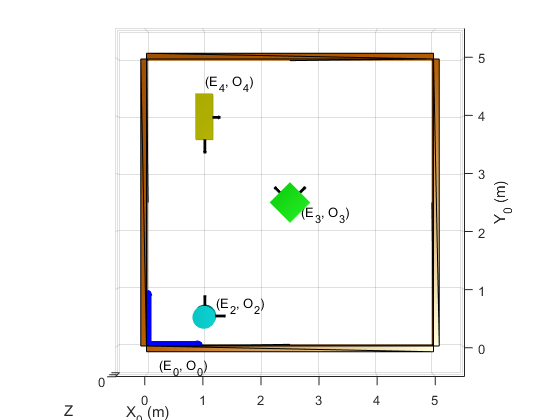

xtext = [0.2, 1.2, 2.7, 1];
ytext = [-0.4, 0.7, 2.3, 4.6];
t = {'(E_0, O_0)', '(E_2, O_2)', '(E_3, O_3)', '(E_4, O_4)'};
text(xtext,ytext,t);

Q1 mobile robot plotting

r_robot = 0.3

r_robot = 0.3000

Robot = collisionCylinder(r_robot,1);
Robot.Pose(1:2,4) = p01_0;
[~,patchRobot] = show(Robot,'Parent',ax);
patchRobot.FaceColor = 'none';
patchRobot.EdgeColor = 'k';
patchRobot.EdgeAlpha = 0.5;
robot_X = p01_0(1);
robot_Y = p01_0(2);
quiver([robot_X;robot_X],[robot_Y;robot_Y],[-0.3;0],[0;0.3],'LineWidth',2,'Color','b')
robTri = polyshape([robot_X + r_robot, robot_X, robot_X],...
    [robot_Y, robot_Y + r_robot/2, robot_Y - r_robot/2]);
robTri = rotate(robTri,atan2(R_01(2,1),R_01(1,1))*180/pi,[robot_X,robot_Y]);
plot(robTri,"FaceColor",'b')

Annotation

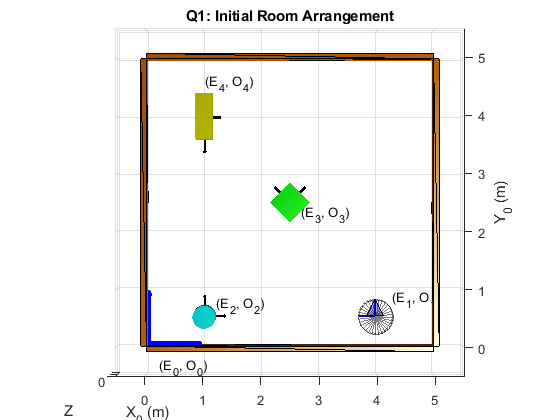

xtext = robot_X+0.3;
ytext = robot_Y+0.3;
t = {'(E_1, O_1)'};
text(xtext,ytext,t);
title('Q1: Initial Room Arrangement')

# Q2:

a)

p01_0 = p04_0 + [0.15 + 0.1 + 0.3; 0]

p01_0 =     1.5500
    4.0000


R_01 = rot2(pi)

R_01 =    -1.0000   -0.0000
    0.0000   -1.0000


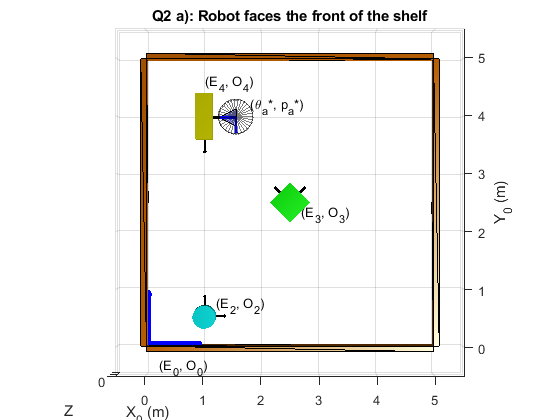


figure;
ax = gca;
mpj1_draw(ax)

r_robot = 0.3;
Robot = collisionCylinder(r_robot,1);
Robot.Pose(1:2,4) = p01_0;
[~,patchRobot] = show(Robot,'Parent',ax);
patchRobot.FaceColor = 'none';
patchRobot.EdgeColor = 'k';
patchRobot.EdgeAlpha = 0.5;
robot_X = p01_0(1);
robot_Y = p01_0(2);
quiver([robot_X;robot_X],[robot_Y;robot_Y],0.3*R_01(1,:)',0.3*R_01(2,:)','LineWidth',2,'Color','b')
robTri = polyshape([robot_X + r_robot, robot_X, robot_X],...
    [robot_Y, robot_Y + r_robot/2, robot_Y - r_robot/2]);
robTri = rotate(robTri,atan2(R_01(2,1),R_01(1,1))*180/pi,[robot_X,robot_Y]);
plot(robTri,"FaceColor",'b')

text(1.8,4.2,'(\theta_a*, p_a*)')
title('Q2 a): Robot faces the front of the shelf')

b)

p01_0 = p02_0 + [0; 0.2 + 0.1 + 0.3]

p01_0 =     1.0000
    1.1000


R_01 = rot2(3*pi/2)

R_01 =    -0.0000    1.0000
   -1.0000   -0.0000


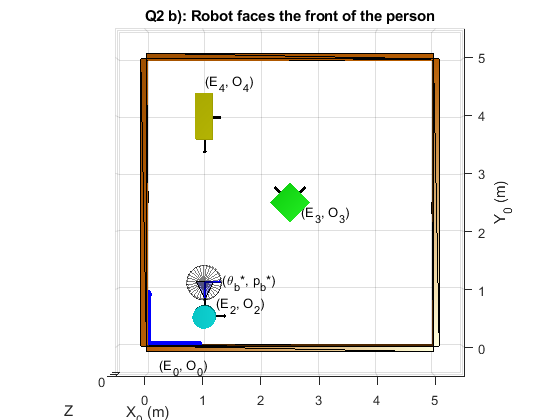


figure;
ax = gca;
mpj1_draw(ax)

r_robot = 0.3;
Robot = collisionCylinder(r_robot,1);
Robot.Pose(1:2,4) = p01_0;
[~,patchRobot] = show(Robot,'Parent',ax);
patchRobot.FaceColor = 'none';
patchRobot.EdgeColor = 'k';
patchRobot.EdgeAlpha = 0.5;
robot_X = p01_0(1);
robot_Y = p01_0(2);
quiver([robot_X;robot_X],[robot_Y;robot_Y],0.3*R_01(1,:)',0.3*R_01(2,:)','LineWidth',2,'Color','b')
robTri = polyshape([robot_X + r_robot, robot_X, robot_X],...
    [robot_Y, robot_Y + r_robot/2, robot_Y - r_robot/2]);
robTri = rotate(robTri,atan2(R_01(2,1),R_01(1,1))*180/pi,[robot_X,robot_Y]);
plot(robTri,"FaceColor",'b')


text(1.3,1.1,'(\theta_b*, p_b*)')
title('Q2 b): Robot faces the front of the person')

# Q3:

a)

b)

% Target makers
pos_0 = [4;0.5]

pos_0 =     4.0000
    0.5000


th_0 = pi/2;
pos_1 = [4;4]

pos_1 =      4
     4


th_1 = pi/2;
pos_2 = [1.55;4]

pos_2 =     1.5500
    4.0000


th_2 = pi;
pos_3 = [1;1.1]

pos_3 =     1.0000
    1.1000


th_3 = 3*pi/2;
% Path 0 to 1 generation
lf = norm(pos_1-pos_0)

lf = 3.5000

l= linspace(0,lf,8);
path0_1 = pos_0*(1-l/lf) + pos_1*l/lf;
orien0_1 = th_0*(1-l/lf) + th_1*l/lf;
% Path 1 to 2 generation
lf = norm(pos_2-pos_1)

lf = 2.4500

l= linspace(0,lf,6);
path1_2 = pos_1*(1-l/lf) + pos_2*l/lf;
orien1_2 = th_1*(1-l/lf) + th_2*l/lf;
% Path 2 to 3 generation
lf = norm(pos_2-pos_1)

lf = 2.4500

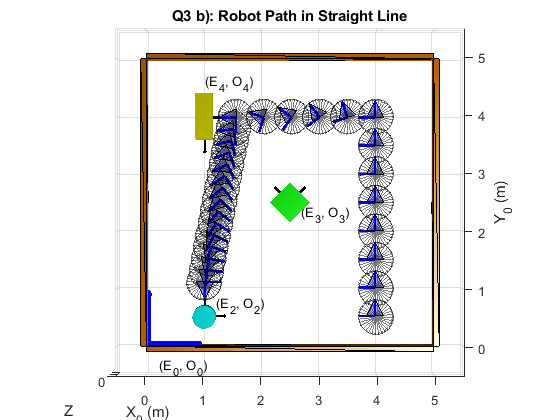

l= linspace(0,lf,15);
path2_3 = pos_2*(1-l/lf) + pos_3*l/lf;
orien2_3 = th_2*(1-l/lf) + th_3*l/lf;

% plotting
path_whole = [path0_1,path1_2,path2_3];
orien_whole = [orien0_1,orien1_2,orien2_3];
figure;
ax = gca;

mpj1_draw(ax);

r_robot = 0.3;
Robot = collisionCylinder(r_robot,1);
for i = 1:size(path_whole,2)
    p01_0 = path_whole(:,i);
    R_01 = rot2(orien_whole(i));
    Robot.Pose(1:2,4) = p01_0;
    [~,patchRobot] = show(Robot,'Parent',ax);
    patchRobot.FaceColor = 'none';
    patchRobot.EdgeColor = 'k';
    patchRobot.EdgeAlpha = 0.5;
    robot_X = p01_0(1);
    robot_Y = p01_0(2);
    quiver([robot_X;robot_X],[robot_Y;robot_Y],0.3*R_01(1,:)',0.3*R_01(2,:)','LineWidth',2,'Color','b')
    robTri = polyshape([robot_X + r_robot, robot_X, robot_X],...
        [robot_Y, robot_Y + r_robot/2, robot_Y - r_robot/2]);
    robTri = rotate(robTri,atan2(R_01(2,1),R_01(1,1))*180/pi,[robot_X,robot_Y]);
    plot(robTri,"FaceColor",'b')
end

title('Q3 b): Robot Path in Straight Line')

c) w/ speed constraint

umax = [2;2]; % meter/sec
wmax = 1; % rad / sec

Path 0 - 1

% unit vector of path
path_v = pos_1-pos_0;
dir_path = (path_v)/norm(path_v);
% max speed along dir_path0_1 so that x0,x1 of umax
% is not violated
l1dotmax = min(abs(umax./dir_path));
% Time takes for path
t_pos = norm(path_v)/l1dotmax;
% rotation change
th_diff = th_1-th_0;
t_th = th_diff/wmax;
% actual time for path
T1 = max(t_pos,t_th)

T1 = 1.7500

The rest

path_v = pos_2-pos_1;
dir_path = (path_v)/norm(path_v);
l2dotmax = min(abs(umax./dir_path));
t_pos = norm(path_v)/l2dotmax;
th_diff = th_2-th_1;
t_th = th_diff/wmax;
T2 = max(t_pos,t_th)

T2 = 1.5708


path_v = pos_3-pos_2;
dir_path = (path_v)/norm(path_v);
l3dotmax = min(abs(umax./dir_path));
t_pos = norm(path_v)/l3dotmax;
th_diff = th_3-th_2;
t_th = th_diff/wmax;
T3 = max(t_pos,t_th)

T3 = 1.5708

Robot path planning 0-1

ts = 0.1; % 0.1 second sampling period
t1_seg = 0:ts:T1; 
path0_1 = zeros(2,length(t1_seg));path0_1(:,1) = pos_0;
th0_1 = zeros(1,length(t1_seg));th0_1(1) = th_0;

path_v = pos_1-pos_0;
dir_path = (path_v)/norm(path_v);

l1dotmax = norm(path_v)/T1;
t1dotmax = (th_1-th_0)/T1;

for i = 2:length(t1_seg)
    path0_1(:,i) = path0_1(:,i-1) + ts*l1dotmax*dir_path;
    th0_1(i) = th0_1(i-1) + ts*t1dotmax;
end
if(any(path0_1(:,end)~=pos_1))
    t1_seg = [t1_seg,T1];
    path0_1 = [path0_1,pos_1];
    th0_1 = [th0_1,th_1];
end

path 1-2

t2_seg = T1:ts:T1+T2; 
path1_2 = zeros(2,length(t2_seg));path1_2(:,1) = pos_1;
th1_2 = zeros(1,length(t2_seg));th1_2(1) = th_1;

path_v = pos_2-pos_1;
dir_path = (path_v)/norm(path_v);

l2dotmax = norm(path_v)/T2;
t2dotmax = (th_2-th_1)/T2;

for i = 2:length(t2_seg)
    path1_2(:,i) = path1_2(:,i-1) + ts*l2dotmax*dir_path;
    th1_2(i) = th1_2(i-1) + ts*t2dotmax;
end
if(any(path1_2(:,end)~=pos_2))
    t2_seg = [t2_seg,T1+T2];
    path1_2 = [path1_2,pos_2];
    th1_2 = [th1_2,th_2];
end

path 2-3

t3_seg = T1+T2:ts:T1+T2+T3; 
path2_3 = zeros(2,length(t3_seg));path2_3(:,1) = pos_2;
th2_3 = zeros(1,length(t3_seg));th2_3(1) = th_2;

path_v = pos_3-pos_2;
dir_path = (path_v)/norm(path_v);

l3dotmax = norm(path_v)/T3;
t3dotmax = (th_3-th_2)/T3;

for i = 2:length(t3_seg)
    path2_3(:,i) = path2_3(:,i-1) + ts*l3dotmax*dir_path;
    th2_3(i) = th2_3(i-1) + ts*t3dotmax;
end
if(any(path2_3(:,end)~=pos_3))
    t3_seg = [t3_seg,T1+T2+T3];
    path2_3 = [path2_3,pos_3];
    th2_3 = [th2_3,th_3];
end

Combine and formating

path_all = [path0_1,path1_2(:,2:end),path2_3(:,2:end)];
th_all = [th0_1,th1_2(:,2:end),th2_3(:,2:end)];
t_all = [t1_seg,t2_seg(:,2:end),t3_seg(:,2:end)];
l_all = [0,cumsum(vecnorm(diff(path_all')'))];

Plotting

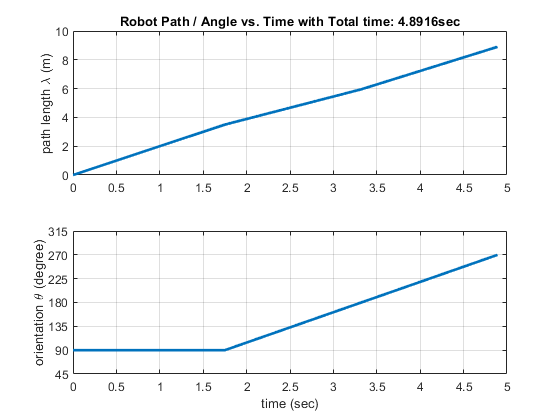

figure;
subplot(2,1,1)
plot(t_all,l_all,'linewidth',2)
title(['Robot Path / Angle vs. Time with Total time: ',num2str(T1+T2+T3),'sec'])
ylabel('path length \lambda (m)')
yticks(0:2:10)
grid on
subplot(2,1,2)
plot(t_all,th_all.*180/pi,'linewidth',2)
ylim([45,315])
yticks(45:45:315)
ylabel('orientation \theta (degree)')
xlabel('time (sec)')
grid on

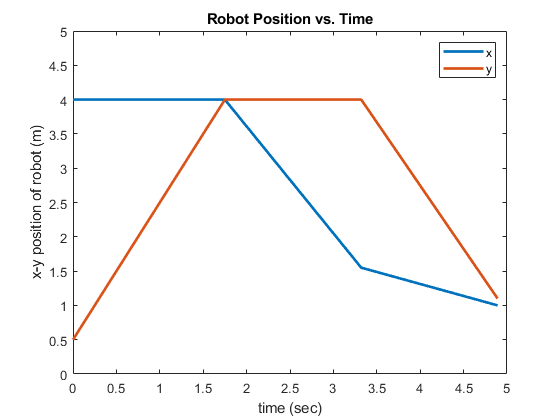

figure;
plot(t_all,path_all,'linewidth',2)
title('Robot Position vs. Time')
legend('x','y')
ylim([0,5])
xlabel('time (sec)')
ylabel('x-y position of robot (m)')

d)

n_p = 7; %num point consided per side
n_a = 4;
n_s = 30;

%kink location
k1 = size(path0_1,2);

kink 1

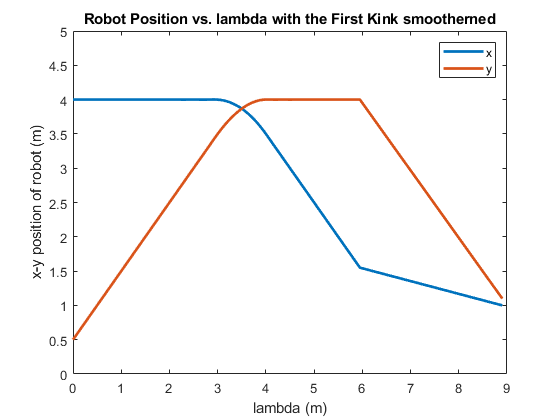


%kink 1 path regenerated
hd = k1-n_p;
tl = k1+n_p;
l_s_1 = l_all(hd):...
    (l_all(tl)-l_all(hd))/n_s:...
    l_all(tl);
p_s_1 = spline([l_all(hd:hd+n_a),l_all(tl-n_a:tl)],...
    path_all(:,[hd:hd+n_a,tl-n_a:tl]),l_s_1);
l_k1 = [l_all(1:hd-1), l_s_1, l_all(tl+1:end)];
path_k1 = [path_all(:,1:hd-1), p_s_1, path_all(:,tl+1:end)];
figure;
plot(l_k1,path_k1,'linewidth',2)
title('Robot Position vs. lambda with the First Kink smootherned')
legend('x','y')
ylim([0,5])
xlabel('lambda (m)')
ylabel('x-y position of robot (m)')

kink 2 need to pass the point

[~,k2] = find(path_k1(1,:) == 1.55 & path_k1(2,:) == 4)

k2 = 51

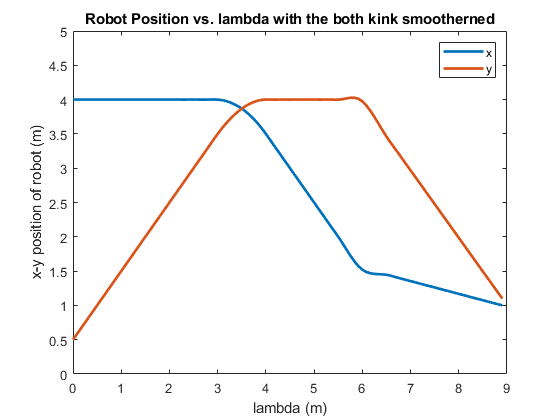

hd = k2-n_p;
tl = k2+n_p;
l_s_2 = l_k1(hd):...
    (l_k1(tl)-l_k1(hd))/n_s:...
    l_k1(tl);
p_s_2 = spline([l_k1(hd:hd+n_a),l_k1(k2),l_k1(tl-n_a:tl)],...
    path_k1(:,[hd:hd+n_a,k2,tl-n_a:tl]),l_s_2);
l_k2 = [l_k1(1:hd-1), l_s_2, l_k1(tl+1:end)];
path_k2 = [path_k1(:,1:hd-1), p_s_2, path_k1(:,tl+1:end)];
figure;
plot(l_k2,path_k2,'linewidth',2)
title('Robot Position vs. lambda with the both kink smootherned')
legend('x','y')
ylim([0,5])
xlabel('lambda (m)')
ylabel('x-y position of robot (m)')

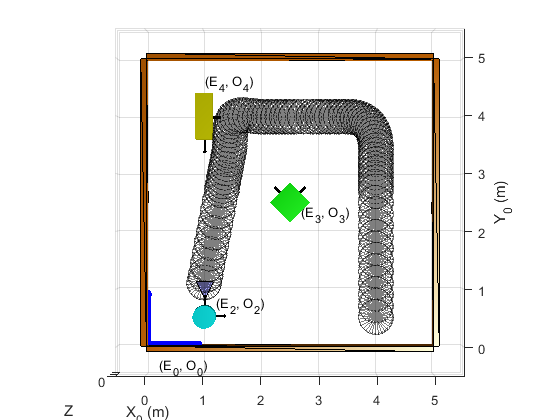

figure;
ax = gca;

mpj1_draw(ax);

r_robot = 0.3;
Robot = collisionCylinder(r_robot,1);
for i = 1:size(path_k2,2)
    p01_0 = path_k2(:,i);
    Robot.Pose(1:2,4) = p01_0;
    [~,patchRobot] = show(Robot,'Parent',ax);
    patchRobot.FaceColor = 'none';
    patchRobot.EdgeColor = 'k';
    patchRobot.EdgeAlpha = 0.5;
    plot(robTri,"FaceColor",'b')
end

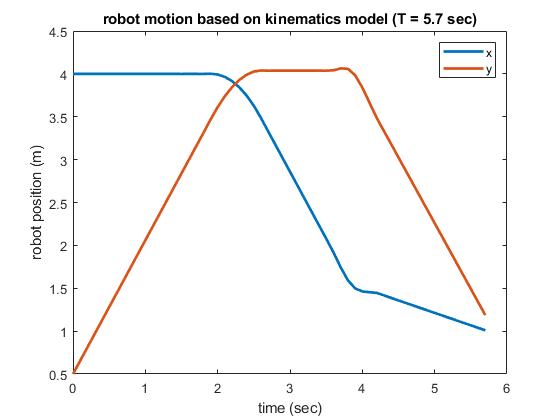

pathws_dir = diff(path_k2')'./diff(l_k2);
l_wsdotmax = min(min(abs(umax./pathws_dir)')');
ldotmax=min([l1dotmax l2dotmax l3dotmax l_wsdotmax]);

T_ws = l_k2(end)/ldotmax;
pathws_dir = [pathws_dir, pathws_dir(:,end)];
tws_seg = 0:ts:T_ws; NT = length(tws_seg);
path_ws = zeros(2,NT); path_ws(:,1) = pos_0;
lt_ws = zeros(size(tws_seg));
pathws_prime = zeros(2,NT);
pathws_prime(:,1)=(path_k2(:,2)-path_k2(:,1))/norm(path_k2(:,2)-path_k2(:,1));
uws = zeros(2,NT-1);
for i=1:NT-1
    uws(:,i) = pathws_prime(:,i)*ldotmax;
    path_ws(:,i+1) = path_ws(:,i)+ts*uws(:,i);
    lt_ws(i+1)=lt_ws(i)+ts*ldotmax;
    xprime=interp1(l_k2(1:end),pathws_dir(1,:),lt_ws(i+1));
    yprime=interp1(l_k2(1:end),pathws_dir(2,:),lt_ws(i+1));
    pathws_prime(:,i+1)=[xprime;yprime];
end

figure;plot(tws_seg,path_ws,'linewidth',2);legend('x','y');
xlabel('time (sec)');ylabel('robot position (m)');
title('robot motion based on kinematics model (T = 5.7 sec)');

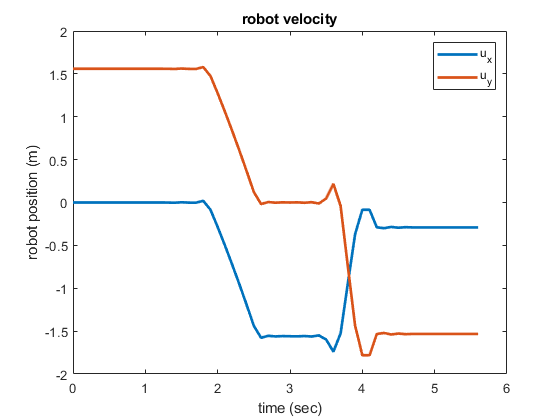


figure;plot(tws_seg(1:end-1),uws,'linewidth',2);legend('u_x','u_y');
xlabel('time (sec)');ylabel('robot position (m)');
title('robot velocity')

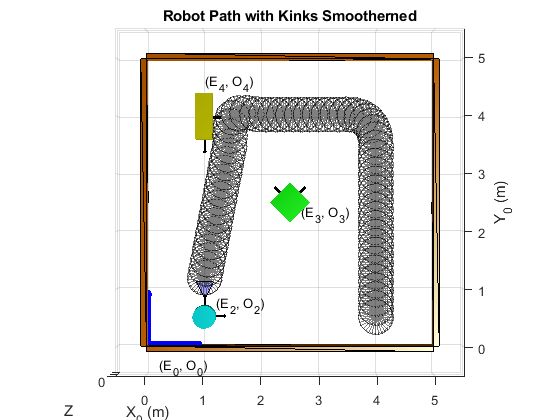

figure;
ax = gca;

mpj1_draw(ax);

r_robot = 0.3;
Robot = collisionCylinder(r_robot,1);
for i = 1:size(path_ws,2)
    p01_0 = path_ws(:,i);
    Robot.Pose(1:2,4) = p01_0;
    [~,patchRobot] = show(Robot,'Parent',ax);
    patchRobot.FaceColor = 'none';
    patchRobot.EdgeColor = 'k';
    patchRobot.EdgeAlpha = 0.5;
    plot(robTri,"FaceColor",'b')
end
title('Robot Path with Kinks Smootherned')